# **Haley et al. (2025) Data Tutorial (Getting Started)**

Below, you will find a quick tutorial to view the *C. elegans* behavior data and *E. coli* fluorescence imaging data which relates to:

- Paper: [https://doi.org/10.7554/eLife.103191.3](https://doi.org/10.7554/eLife.103191.3)

- Dataset: [https://doi.org/10.63884/ndic.2025.pb77mj2s](https://ndi-cloud.com/datasets/10.63884/ndic.2025.pb77mj2s)

## Import the NDI dataset

Define the dataset path and id.

% Choose the folder where the dataset is (or will be) stored
% (e.g. /Users/myusername/Documents/MATLAB/Datasets)
% dataPath = fullfile(userpath,'Datasets');
% cloudDatasetId = '682e7772cdf3f24938176fac';
% datasetPath = fullfile(dataPath,cloudDatasetId);
datasetPath = fullfile(userpath,'data','haley','haley_2025');

### Download or load the NDI dataset 

The first time you try to access the data, it needs to be downloaded from [NDI Cloud](https://ndi-cloud.com/). This may take a few minutes. Once you have the **dataset** downloaded, every other time you examine the data you can just load it.

if isfolder(datasetPath)
    % Load if already downloaded
    dataset = ndi.dataset.dir(datasetPath);
else
    % Download
    if ~isfolder(dataPath), mkdir(dataPath); end
    dataset = ndi.cloud.downloadDataset(cloudDatasetId,dataPath);
end

### Retrieve the NDI session

A **dataset** can have multiple **sessions**. This **dataset** has one **session** for *C. elegans* behavior and one **session** for *E. coli* fluorescence imaging data.

% Retrieve the sessions from this dataset
[session_ref,session_list] = dataset.session_list();
session_Celegans = dataset.open_session(session_list{contains(session_ref,'Celegans')});
session_Ecoli = dataset.open_session(session_list{contains(session_ref,'Ecoli')});

### View NDI file types

Each NDI **dataset** is composed of .json documents and associated binary files. Let's start by taking a look at the **document** types in this **dataset**. We'll subsequently explore each of these below.

[docTypes,docCounts] = ndi.fun.doc.getDocTypes(dataset);
documentsNDI = table(docTypes,docCounts)

documentsNDI = 13×2 table
            docTypes             docCounts
    _________________________    _________

    {'dataset_session_info' }          1  
    {'distance_metadata'    }       2078  
    {'element'              }       4156  
    {'element_epoch'        }       4156  
    {'imageStack_parameters'}       8081  
    {'ontologyImage'        }       2950  
    {'ontologyTableRow'     }      41095  
    {'openminds'            }          8  
    {'openminds_subject'    }       9032  
    {'position_metadata'    }       2078  
    {'session'              }          3  
    {'subject'              }       1656  
    {'treatment'            }         56  


## View *C. elegans* dataset

In these next few sections we will look at the *C. elegans* **session**. Later, we will look at the *E. coli* **session**.

### Retrieve experiment metadata

Most of the metadata about these experiments such as information about the agar plates used for cultivation and behavioral assay of the animals is stored in `ontologyTableRow` documents. Each document contains one row of data. We'll start by retrieving the information from these documents and placing them in their respective tables. The *C. elegans* **dataset** has 6 different data tables which store information related to the 1) **subjects**, 2) cultivation plates, 3) behavior plates, 4) bacterial patches, 5) mapping of plates to subjects, and 6) analysis of patch encounters. We'll walk through retrieving each of these.

% Get documents/table
query = ndi.query('','isa','ontologyTableRow');
docs = session_Celegans.database_search(query);
[dataTables,docIDs] = ndi.fun.doc.ontologyTableRowDoc2Table(docs); % this may take a minute

% Add relevant document identifiers
dataTables{1} = addvars(dataTables{1},docIDs{1}',...
    'NewVariableNames','BacterialPatchDocumentIdentifier'); % add patch document identifier
dataTables{2} = addvars(dataTables{2},docIDs{2}',...
    'NewVariableNames','BacterialPlateDocumentIdentifier'); % add plate document identifier
dataTables{3} = addvars(dataTables{3},docIDs{3}',...
    'NewVariableNames','BacterialPlateDocumentIdentifier'); % add plate document identifier

#### View ontology term definitions

We can look at the variables stored in these `ontologyTableRow` documents and their well-defined meanings linked to an **ontology**.

% Get list of all variables
[fullNames,~,ontologyNodes] = ndi.fun.doc.ontologyTableRowVars(session_Celegans);

% Select a variable to view it's definition
fullName = fullNames(29);

% Look up the variable in the ontology
termIndex = strcmp(fullNames,fullName{1});
termID = ontologyNodes{termIndex};
[id,name,~,definition,~,shortName] = ndi.ontology.lookup(termID);

% Display the variable's id, name, definition, and short name
variableInfo = cell2table({id,name,definition,shortName}',...
    'RowNames',{'id','name','definition','shortName'},...
    'VariableNames',{'value'})

variableInfo = 4×1 table
                                                                                   value                                                                  
                  ________________________________________________________________________________________________________________________________________

    id            {'EMPTY:00000223'                                                                                                                      }
    name          {'bacterial patch radius'                                                                                                              }
    definition    {'The radius of an individual detected bacterial patch on an agar plate, assuming patches are circular or near-circular. Unit: pixels.'}
    shortName     {'BacterialPatchRadius'                                                        

### View subject summary table

Each individual animal is referred to as a **subject** and has a unique alphanumeric `SubjectDocumentID` and `SubjectLocalID`. This dataset contains `ontologyTableRow``,` `subject`, `openminds_subject`, and `openminds` documents which store metadata about each **subject** including their species, strain, genetic strain type, and biological sex which are linked to well-defined ontologies such as NCBI and WormBase. Additionally, metadata about any **treatments** that a **subject** received such as food deprivation are stored in `treatment` documents. A summary table showing the metadata for each **subject** can be viewed below.

% View summary table of all subject metadata
subjectSummary = ndi.fun.subjectDocTable(session_Celegans); % this will take several minutes
subjectTable = ndi.fun.table.join({dataTables{6},subjectSummary}) % adds subject metadata to subject table

subjectTable = 1656×12 table
    SubjectIdentifier                         SubjectLocalIdentifier                                SubjectDocumentIdentifier                 SpeciesName             SpeciesOntology      StrainName       StrainOntology        GeneticStrainTypeName    BiologicalSexName    BiologicalSexOntology    Treatment_FoodRestrictionOnsetTime    Treatment_FoodRestrictionOffsetTime
    _________________    _________________________________________________________________    _____________________________________    __________________________    __________________    __________    _____________________    _____________________    _

#### Filter subjects

We have created tools to filter a table by it's values. Try finding **subjects** matching a given criterion.

% Search for subjects
columnNamesSubject = subjectTable.Properties.VariableNames;
columnName = columnNamesSubject(6);
dataValue = "PR811";
rowInd = ndi.fun.table.identifyMatchingRows(subjectTable,...
    columnName{1},dataValue,'stringMatch','contains');
filteredSubjects = subjectTable(rowInd,:)

filteredSubjects = 76×12 table
    SubjectIdentifier                           SubjectLocalIdentifier                                 SubjectDocumentIdentifier                 SpeciesName             SpeciesOntology       StrainName                   StrainOntology                  GeneticStrainTypeName      BiologicalSexName    BiologicalSexOntology    Treatment_FoodRestrictionOnsetTime    Treatment_FoodRestrictionOffsetTime
    _________________    ____________________________________________________________________    _____________________________________    __________________________    __________________    _____________    ________________________________________

### View bacterial plate summary tables

Let's combine all of the information about the behavior plates and patches.

behaviorPlateTable = ndi.fun.table.join(dataTables(1:2)) % add patch data to behavior plates

behaviorPlateTable = 6206×30 table
    BacterialPlateIdentifier    BacterialPatchIdentifier    BacterialOd600TargetAtSeeding    BacterialPatchVolume    BacterialPatchCenter_XCoordinate    BacterialPatchCenter_YCoordinate    BacterialPatchRadius    BacterialPatchCircularity      BacterialPatchDocumentIdentifier       ExperimentSessionIdentifier    CElegansAssayPhase    CElegansBehavioralAssayLabel    DataExclusionFlag    BacterialOd600Label    BacterialPlateGrowthDurationLabel    BacterialPlatePeptoneInclusionFlag      BacterialStrainDocumentIdentifier      BacterialPlateSeedingTimestamp    BacterialPlateColdStorageTimestamp    BacterialPlateRoomTemperatureTimes

As well as the cultivation plates.

cultivationPlateTable = dataTables{3} % cultivation plate data

cultivationPlateTable = 100×23 table
    ExperimentSessionIdentifier    CElegansAssayPhase    BacterialPlateIdentifier    DataExclusionFlag    BacterialOd600Label    BacterialPlateGrowthDurationLabel    BacterialPlatePeptoneInclusionFlag      BacterialStrainDocumentIdentifier      CElegansPickedTimestamp     BacterialPlateSeedingTimestamp    BacterialPlateColdStorageTimestamp    BacterialPlateRoomTemperatureTimestamp    CElegansDevelopmentalStage    BacteriaGrowthDurationAfterSeeding    BacterialOd600Measurement    BacterialColonyFormingUnitsCfuMeasurement    CElegansBehavioralAssay_PlateOrArenaDiameter    BacterialPatchSpacingTarget    AmbientTemperature    Ba

We also have a table that maps each subject to its respective cultivation and behavior plates using their `SubjectDocumentIdentifier` and `BacterialPlateDocumentIdentifier`.

subjectPlateTable = dataTables{4} % subject to plate mapping

subjectPlateTable = 3312×2 table
          SubjectDocumentIdentifier            BacterialPlateDocumentIdentifier   
    _____________________________________    _____________________________________

    {'412693e7323cd3c9_40dc42e5a3227f64'}    {'412693e731e789e5_c0dc992ac33b6c9d'}
    {'412693e7323cf2a2_c0dc1aa818f39d35'}    {'412693e731e789e5_c0dc992ac33b6c9d'}
    {'412693e7323d0e70_c0d11673325adedc'}    {'412693e731e789e5_c0dc992ac33b6c9d'}
    {'412693e7323d2879_40d6765af998bf9c'}    {'412693e731e789e5_c0dc992ac33b6c9d'}
    {'412693e7323d3d1c_40d79079f8ab3fbe'}    {'412693e731e7a0c0_c0b6021c931269d0'}
    {'412693e7323d55a4_40d82336721dc306'}    {'412693e731e7a0c0_c0b6021c931269d0'}
    {'412693e7323d6c76_40dbcd856e5c9cea'}    {'412693e731e7a0c0_c0b6021c931269d0'}
    {'412693e7323d8039_c0d815bc535b7e8e'}    {'412693e731e7a0c0_c0b6021c931269d0'}
    {'412693e7323d98b8_c0df9cf2a6e0fe30'}    {'412693e731e7a384_c0c4

### Retrieve *C. elegans* subject behavior

Now let's choose a **subject** and look at all of the information we have available in the dataset.

% Choose a subject to view its behavior data and metadata
subjectLocalIDs = subjectTable.SubjectLocalIdentifier;
subjectLocalID =subjectLocalIDs(360);

#### Get subject and bacterial plate metadata

% Get subject document id
indSubjectTable = strcmp(subjectTable.SubjectLocalIdentifier,subjectLocalID{1});
subject_id = subjectTable.SubjectDocumentIdentifier{indSubjectTable};

% Get cultivation and behavior plate ids
indSubjectPlateTable = strcmp(subjectPlateTable.SubjectDocumentIdentifier,subject_id);
plateDocumentIDs = subjectPlateTable.BacterialPlateDocumentIdentifier(indSubjectPlateTable);
indCultivationPlateTable = find(ndi.fun.table.identifyMatchingRows(cultivationPlateTable,...
    'BacterialPlateDocumentIdentifier',plateDocumentIDs),1);
cultivationPlate_id = cultivationPlateTable.BacterialPlateDocumentIdentifier(indCultivationPlateTable);
indBehaviorPlateTable = find(ndi.fun.table.identifyMatchingRows(behaviorPlateTable,...
    'BacterialPlateDocumentIdentifier',plateDocumentIDs),1);
behaviorPlate_id = behaviorPlateTable.BacterialPlateDocumentIdentifier(indBehaviorPlateTable);

% Retrieve subject metadata
currentSubject = subjectTable(indSubjectTable,:)

currentSubject = 1×12 table
    SubjectIdentifier                         SubjectLocalIdentifier                                SubjectDocumentIdentifier                 SpeciesName             SpeciesOntology      StrainName       StrainOntology        GeneticStrainTypeName    BiologicalSexName    BiologicalSexOntology    Treatment_FoodRestrictionOnsetTime    Treatment_FoodRestrictionOffsetTime
    _________________    _________________________________________________________________    _____________________________________    __________________________    __________________    __________    _____________________    _____________________    __

% Retrieve plate metadata
currentPlates = ndi.fun.table.vstack({cultivationPlateTable(indCultivationPlateTable,:),...
    behaviorPlateTable(indBehaviorPlateTable,:)})

currentPlates = 2×30 table
    ExperimentSessionIdentifier    CElegansAssayPhase    BacterialPlateIdentifier    DataExclusionFlag    BacterialOd600Label    BacterialPlateGrowthDurationLabel    BacterialPlatePeptoneInclusionFlag      BacterialStrainDocumentIdentifier      CElegansPickedTimestamp     BacterialPlateSeedingTimestamp    BacterialPlateColdStorageTimestamp    BacterialPlateRoomTemperatureTimestamp    CElegansDevelopmentalStage    BacteriaGrowthDurationAfterSeeding    BacterialOd600Measurement    BacterialColonyFormingUnitsCfuMeasurement    CElegansBehavioralAssay_PlateOrArenaDiameter    BacterialPatchSpacingTarget    AmbientTemperature    BacterialPat

#### Get position of subject over time

In the NDI framework, an **element** is a physical (e.g. an instrument that takes a measurement or produces a stimulus) or inferred object (e.g. simulated data). In these experiments, there are 2 element types:

- `position`

- `distance`

Each subject is linked to a unique set of elements. The **position** elements in this dataset are connected to the X,Y coordinate location of each **subject** over time in the behavioral video recording. The **distance** elements in this dataset are connected to the distance between each **subject** and the nearest bacterial patch. For now, let's read the timeseries of this subject's **position** element.

% Get the position element document (one per subject)
queryDocType = ndi.query('element.type','exact_string','position');
queryDependency = ndi.query('','depends_on','subject_id',subject_id);
positionDoc = session_Celegans.database_search(queryDocType & queryDependency);

% Convert to NDI object
positionElement = ndi.database.fun.ndi_document2ndi_object(positionDoc{1}, session_Celegans);

% Read position timeseries
[position,time] = positionElement.readtimeseries(1,-Inf,Inf);

Each `position` **element** is associated with a `position_metadata` document which specifies what the `position` **timeseries** is tracking along with defining the dimensions and units.

% Get the position_metadata document (one per subject)
queryDocType = ndi.query('','isa','position_metadata');
queryDependency = ndi.query('','depends_on','element_id',positionElement.id);
doc = session_Celegans.database_search(queryDocType & queryDependency);

% Get position_metadata ontology nodes
position_metadata = doc{1}.document_properties.position_metadata;
metadataFields = fields(position_metadata);
positionMetadata = {};
for i = 1:numel(metadataFields)
    termIDs = strsplit(position_metadata.(metadataFields{i}),',');
    for j = 1:numel(termIDs)
        [id,name,~,definition,~,shortName] = ndi.ontology.lookup(termIDs{j});

        % Display the variable's id, name, definition, and short name
        positionMetadata{end+1} = cell2table({metadataFields{i},id,name,definition,shortName},...
            'VariableNames',{'field','id','name','definition','shortName'});
    end
end
positionMetadata = ndi.fun.table.vstack(positionMetadata)

positionMetadata = 4×5 table
         field                  id                     name                                                                 definition                                                            shortName      
    ________________    __________________    _______________________    ________________________________________________________________________________________________________________    ____________________

    {'ontologyNode'}    {'EMPTY:00000234'}    {'C. elegans midpoint'}    {'The center point of the C. elegans body.'                                                                    }    {'CElegansMidpoint'}
    {'units'       }    {'NCIT:C48367'   }    {'Pixel'              }    {'The smallest resolvable rectangular area of an image, either on a screen or stored in memory.' 

#### Get behavioral video metadata

An additional **document** type known as `imageStack_parameters` contains relevant metadata associated with the behavioral video recordings.

% Query documents
queryDocType = ndi.query('','isa','imageStack_parameters');
queryDependency = ndi.query('','depends_on','ontologyTableRow_id',behaviorPlate_id);
doc = session_Celegans.database_search(queryDocType & queryDependency);

% Create table
videoParameters = vlt.data.flattenstruct2table(doc{1}.document_properties.imageStack_parameters)

videoParameters = 1×9 table
    dimension_order      dimension_labels       dimension_size    dimension_scale         dimension_scale_units          data_type    data_limits     timestamp         clocktype     
    _______________    _____________________    ______________    _______________    ________________________________    _________    ____________    _________    ___________________

        {'YXT'}        {'height,width,time'}     {3×1 double}      {3×1 double}      {'micrometer,micrometer,second'}    {'uint8'}    {2×1 double}    7.386e+05    {'exp_global_time'}


#### Get associated images and masks

Another **document** type known as `ontologyImage` contains images related to each experiment. 

% Query documents
queryDocType = ndi.query('','isa','ontologyImage');
queryDependency = ndi.query('','depends_on','ontologyTableRow_id',behaviorPlate_id);
docs = session_Celegans.database_search(queryDocType & queryDependency);

% Get ontology image nodes
ontologyImage = cell(size(docs));
for i = 1:numel(docs)
    termID = docs{i}.document_properties.ontologyImage.ontologyNodes;
    [id,name,~,definition,~,shortName] = ndi.ontology.lookup(termID);

    % Display the variable's id, name, definition, and short name
    ontologyImage{i} = cell2table({id,name,definition,shortName},...
        'VariableNames',{'id','name','definition','shortName'});
end
imageTypes = ndi.fun.table.vstack(ontologyImage)

imageTypes = 5×4 table
            id                                        name                                                                                                                                                  definition                                                                                                                                           shortName                      
    __________________    _____________________________________________________________    ____________________________________________________________________________________________________________________________________________________________________________________________________________________________________________    _____________________________________________________

    {'EMPTY:00000226'}    {'C. elegans behavioral assay: first frame i

#### Plot an image/mask with subject position

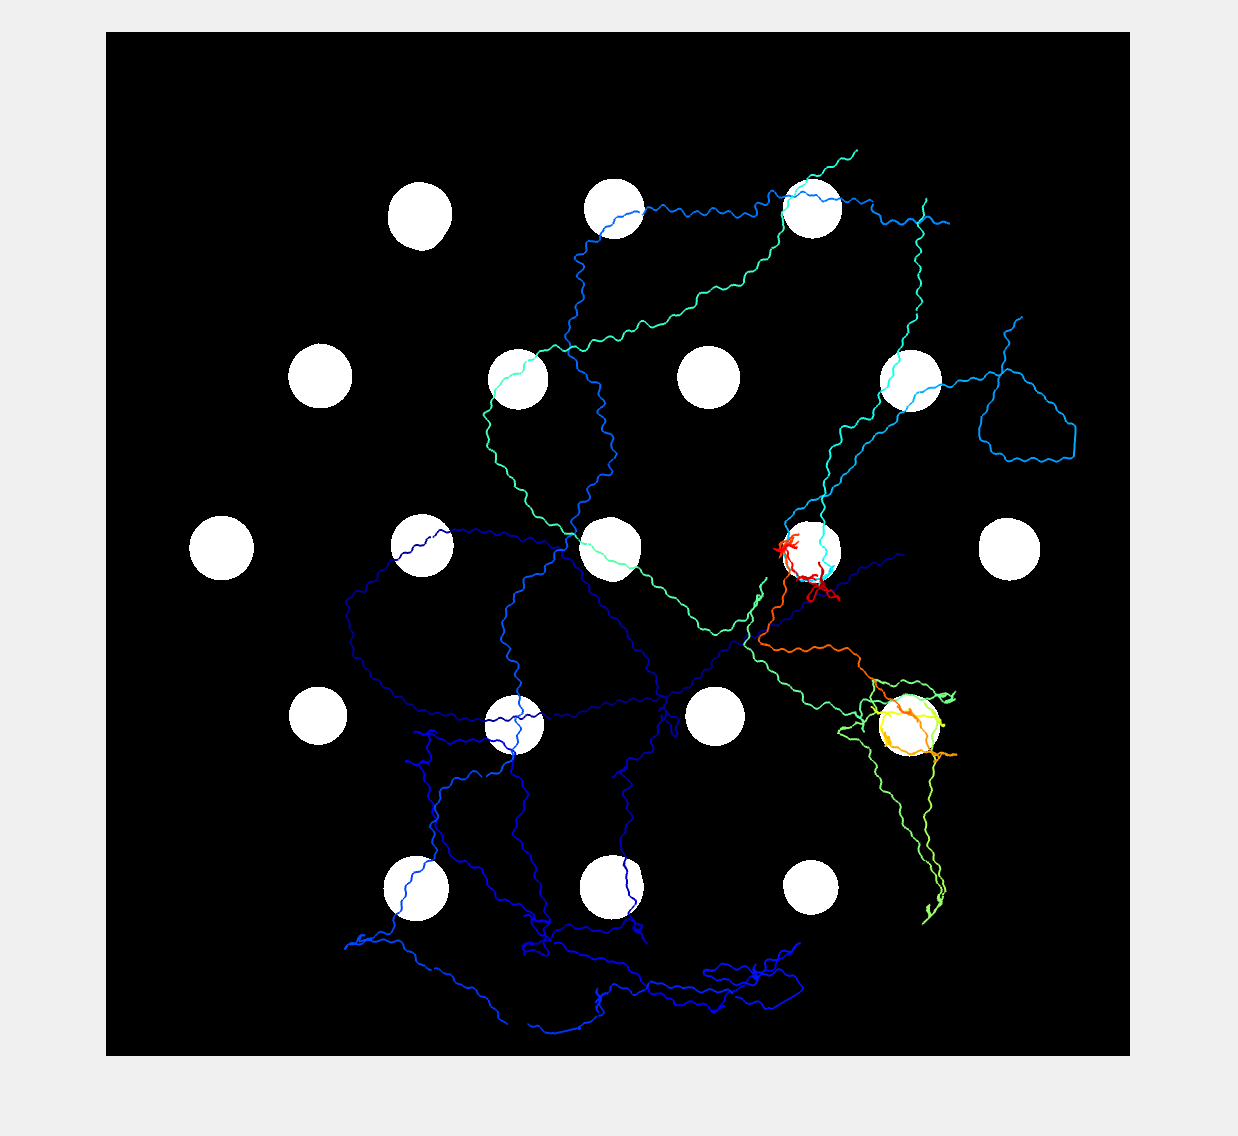

% Choose an image type
imageNames = imageTypes.name;
imageName = imageNames(3);
indImage = strcmp(imageTypes.name,imageName{1});

% Get image data
doc = docs{indImage};
ngrid = doc.document_properties.ngrid;
binaryImage = session_Celegans.database_openbinarydoc(doc,'ontologyImage.ngrid');
image = ndi.fun.data.readngrid(binaryImage,ngrid.data_dim,ngrid.data_type);

% Plot image and position
figure('Visible', 'on');
image = mat2gray(image);
imshow(flip(image)); hold on;
set(gca,'YDir','normal','XTick',[],'YTick',[],...
    'XLim',[1 size(image,1)],'YLim',[1 size(image,2)]);
bins = linspace(min(time),max(time),60);
c = jet(length(bins));
for j = 1:length(bins)-1
    ind = time >= bins(j) & time <= bins(j+1);
    p = plot(position(ind,1),position(ind,2),'Color',c(j,:),'LineWidth',1);
end

#### Get distance to patch edge over time

Now let's take a look at the `distance` **element** timeseries and it's associated. Each `position` **element** is associated with a `distance_metadata` which specifies what the `distance` **timeseries** is tracking along with defining the dimensions and units.

% Get the position element document (one per subject)
queryDocType = ndi.query('element.type','exact_string','distance');
queryDependency = ndi.query('','depends_on','subject_id',subject_id);
distanceDoc = session_Celegans.database_search(queryDocType & queryDependency);

% Convert to NDI object
distanceElement = ndi.database.fun.ndi_document2ndi_object(distanceDoc{1}, session_Celegans);

% Read distance timeseries
[distance,time,timeref] = distanceElement.readtimeseries(1,-Inf,Inf);

% Get the distance_metadata document (one per subject)
queryDocType = ndi.query('','isa','distance_metadata');
queryDependency = ndi.query('','depends_on','element_id',distanceElement.id);
doc = session_Celegans.database_search(queryDocType & queryDependency);

% Get distance_metadata ontology nodes
distance_metadata = doc{1}.document_properties.distance_metadata;
metadataFields = fields(distance_metadata);
distanceMetadata = {};
for i = 1:numel(metadataFields)
    if contains(metadataFields{i},'ontologyNode') || contains(metadataFields{i},'unit')
    termIDs = strsplit(distance_metadata.(metadataFields{i}),',');
    for j = 1:numel(termIDs)
        [id,name,~,definition,~,shortName] = ndi.ontology.lookup(termIDs{j});

        % Display the variable's id, name, definition, and short name
        distanceMetadata{end+1} = cell2table({metadataFields{i},id,name,definition,shortName},...
            'VariableNames',{'field','id','name','definition','shortName'});
    end
    end
end
distanceMetadata = ndi.fun.table.vstack(distanceMetadata)

distanceMetadata = 3×5 table
          field                   id                             name                                                                                                             definition                                                                                                         shortName              
    __________________    __________________    _______________________________________    _________________________________________________________________________________________________________________________________________________________________________________________    ____________________________________

    {'ontologyNode_A'}    {'EMPTY:00000193'}    {'subject document identifier'        }    {'A unique alphanumeric identifier assigned to an NDI subject document.'   

% Get distance_metadata mapping
distanceMap_A = cell2table([num2cell(distance_metadata.integerIDs_A),...
    strsplit(distance_metadata.ontologyStringValues_A,',')'],...
    'VariableNames',{'ObjectNum_A',distanceMetadata.shortName{1}}); % get map
distanceMap_A = ndi.fun.table.join({distanceMap_A,subjectTable}) % add subject data

distanceMap_A = 1×13 table
    ObjectNum_A          SubjectDocumentIdentifier          SubjectIdentifier                         SubjectLocalIdentifier                                 SpeciesName             SpeciesOntology      StrainName       StrainOntology        GeneticStrainTypeName    BiologicalSexName    BiologicalSexOntology    Treatment_FoodRestrictionOnsetTime    Treatment_FoodRestrictionOffsetTime
    ___________    _____________________________________    _________________    _________________________________________________________________    __________________________    __________________    __________    _____________________</

distanceMap_B = cell2table([num2cell(distance_metadata.integerIDs_B),...
    strsplit(distance_metadata.ontologyStringValues_B,',')'],...
    'VariableNames',{'ObjectNum_B',distanceMetadata.shortName{2}}); % get map
distanceMap_B = ndi.fun.table.join({distanceMap_B,behaviorPlateTable}) % add patch data

distanceMap_B = 19×31 table
    ObjectNum_B      BacterialPatchDocumentIdentifier       BacterialPlateIdentifier    BacterialPatchIdentifier    BacterialOd600TargetAtSeeding    BacterialPatchVolume    BacterialPatchCenter_XCoordinate    BacterialPatchCenter_YCoordinate    BacterialPatchRadius    BacterialPatchCircularity    ExperimentSessionIdentifier    CElegansAssayPhase    CElegansBehavioralAssayLabel    DataExclusionFlag    BacterialOd600Label    BacterialPlateGrowthDurationLabel    BacterialPlatePeptoneInclusionFlag      BacterialStrainDocumentIdentifier      BacterialPlateSeedingTimestamp    BacterialPlateColdStorageTimestamp    Bacterial

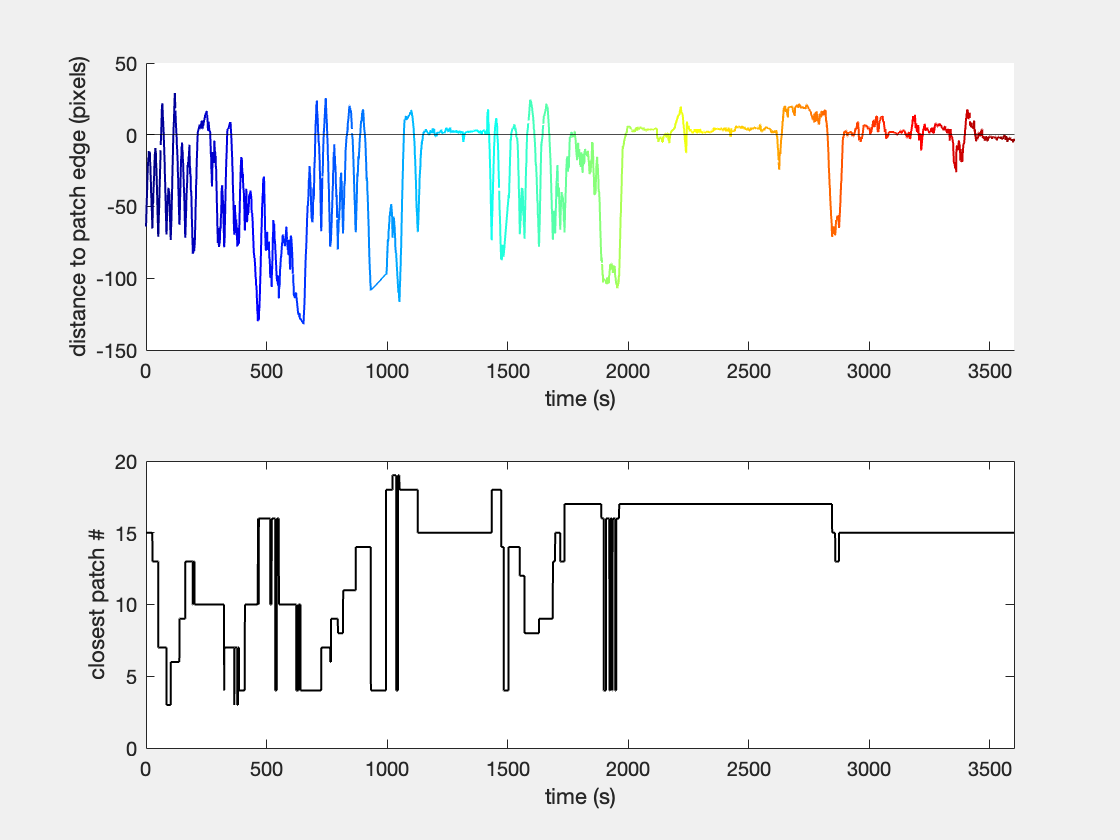

% Plot distance
figure('Visible','on'); 
ax1 = subplot(211); hold on
yline(0,'k')
bins = linspace(min(time),max(time),60);
c = jet(length(bins));
for j = 1:length(bins)-1
    ind = time >= bins(j) & time <= bins(j+1);
    p = plot(time(ind),distance(ind,1),'Color',c(j,:),'LineWidth',1);
end
xlabel('time (s)'); ylabel('distance to patch edge (pixels)'); xlim(prctile(time,[0 100])); 
ax2 = subplot(212); plot(time,distance(:,3),'k','LineWidth',1);
xlabel('time (s)'); ylabel('closest patch #'); xlim(prctile(time,[0 100]));

### Get analysis of patch encounters

Finally, let's view the analysis of patch encounters for this **subject**. This data is stored in `ontologyTableRow` documents.

encounterTable = dataTables{5}; % get ontologyTableRow table
indEncounterTable = ndi.fun.table.identifyMatchingRows(encounterTable,...
    'SubjectDocumentIdentifier',subject_id); 
currentEncounters = encounterTable(indEncounterTable,:); % get rows associated with subject
currentEncounters = ndi.fun.table.join({currentEncounters,behaviorPlateTable}) % add patch data

currentEncounters = 21×42 table
          SubjectDocumentIdentifier          CElegansBehavioralAssay_EncounterIdentifier      BacterialPatchDocumentIdentifier       CElegansBehavioralAssay_EncounterOnsetTime    CElegansBehavioralAssay_EncounterOffsetTime    CElegansBehavioralAssay_DecelerationUponEncounter    CElegansBehavioralAssay_MinimumVelocityDuringEncounter    CElegansBehavioralAssay_PeakVelocityBeforeEncounterOnset    CElegansBehavioralAssay_MinimumVelocityAfterEncounterOffset    CElegansBehavioralAssay_PosteriorProbabilityOfExploitation    CElegansBehavioralAssay_PosteriorProbabilityOfSensing    CElegansBehavioralAssay_RelativeDensityOfEncounteredBacteria    CElegansBehavioralAssay_RelativeDensityOfCultivationBacteria    BacterialPlateIdentifier

### View element summary table

% View summary table of all probe metadata
elementSummary = ndi.fun.elementDocTable(session_Celegans) % this will take several minutes

## View *E. coli* dataset

Each NDI **dataset** is composed of .json documents and associated files. Let's start by taking a look at the **document** types in this dataset.

uniqueDocTypes = ndi.fun.doc.getDocTypes(session_Ecoli)'

Let's start by examing the ontologyTableRow documents below.

### View experiment metadata

Now let's take a look at the `ontologyTableRow` documents. These contain most of the metadata about these experiments. We can start by taking a look at what variables are stored in these documents.

% Get list of all variables
[fullNames,shortNames,ontologyNodes] = ...
    ndi.fun.doc.ontologyTableRowVars(session_Ecoli);

% Select a variable to view it's definition
fullName = fullNames(1);

% Look up the variable in the ontology
termIndex = strcmp(fullNames,fullName{1});
termID = ontologyNodes{termIndex};
[id,name,prefix,definition,synonyms,shortName] = ...
    ndi.ontology.lookup(termID);

% Display the variable's id, name, definition, and short name
variableInfo = cell2table({id,name,definition,shortName}',...
    'RowNames',{'id','name','definition','shortName'},...
    'VariableNames',{'value'})

Now let's retrieve the information from these documents and place them in tables. The *E. coli* dataset has 3 different data tables which store information related to the 1) bacterial plates, 2) microscopy images, 3) analysis of patches in each image.

% Get documents/table
query = ndi.query('','isa','ontologyTableRow');
docs = session_Ecoli.database_search(query);
[dataTables,docIDs] = ndi.fun.doc.ontologyTableRowDoc2Table(docs,'SeparateByType',true);

Let's combine all of the data into a big table with one row per patch per time point.

dataTables{2} = addvars(dataTables{2},docIDs{2}',...
    'NewVariableNames','ImageDocumentIdentifier'); % add image document identifier
bacteriaTable = ndi.fun.table.join(dataTables([3,2,1]))

Let's look at the `imageStack_parameters` documents.

% Choose an image to view its properties
imageIDs = bacteriaTable.MicroscopyImageIdentifier;
imageID = imageIDs(1);
indImage = strcmp(bacteriaTable.MicroscopyImageIdentifier,imageID{1});
image_id = bacteriaTable.ImageDocumentIdentifier{indImage};

% Query documents
queryDocType = ndi.query('','isa','imageStack_parameters');
queryDependency = ndi.query('','depends_on','ontologyTableRow_id',image_id);
doc = session_Ecoli.database_search(queryDocType & queryDependency);

% Create table
videoParameters = vlt.data.flattenstruct2table(doc{1}.document_properties.imageStack_parameters)

Finally, let's look at `openminds` documents.

queryDocType = ndi.query('','isa','openminds');
docs = session_Ecoli.database_search(queryDocType);